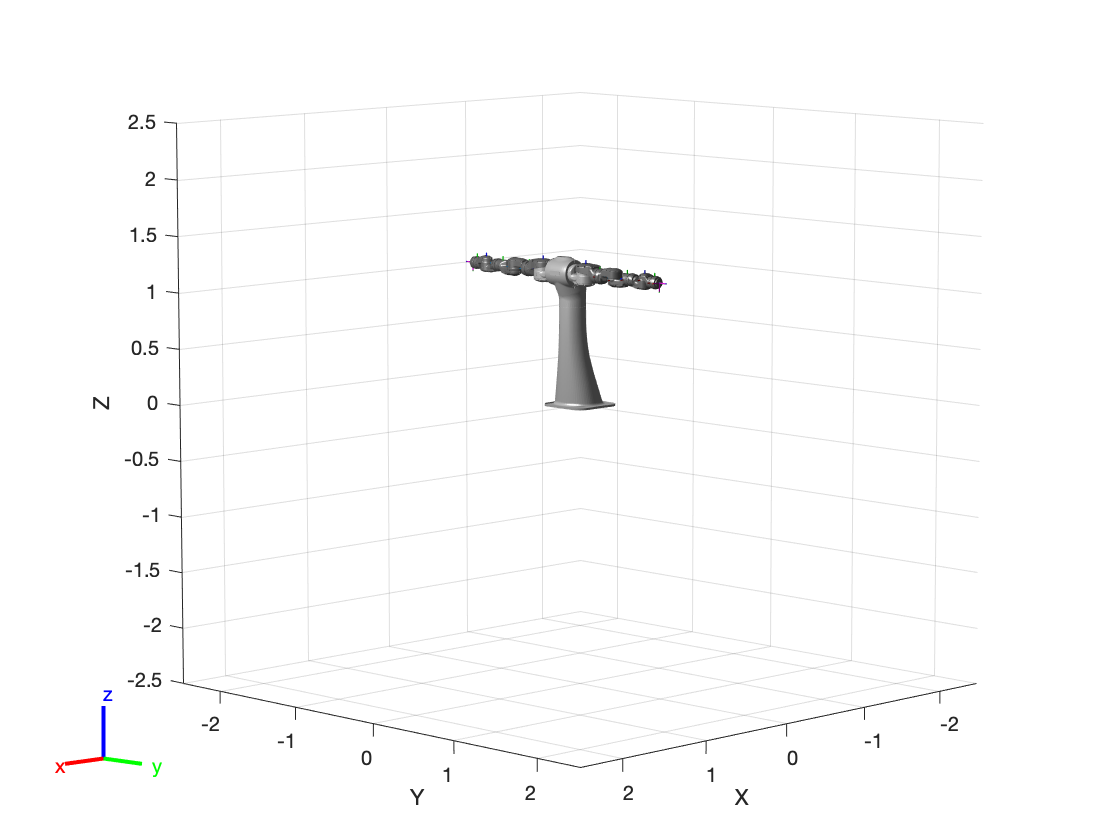

ans =   Axes (Primary) with properties:

             XLim: [-2.5000 2.5000]
             YLim: [-2.5000 2.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


% function []=robotmotion(thetas_before,thetas_after)
%test case
% clear
thetas_before=[0;0;0;0;0;0;0];
thetas_after=[pi/4; pi/3; pi/2; -pi/3; pi/4; -pi/4; 3*pi/4];
%
robot = importrobot('csda10f.urdf',"DataFormat","column");
show(robot)

tspan = 0:0.001:3;
initialState = [homeConfiguration(robot); thetas_before];
targetState = [thetas_after; zeros(7,1); zeros(7,1)];
motionModel = jointSpaceMotionModel("RigidBodyTree",robot);
updateErrorDynamicsFromStep(motionModel,.3,.05);
[t,robotState] = ode45(@(t,state)derivative(motionModel,state,targetState),tspan,initialState);

Error using derivative
Expected state to be an array with number of elements equal to 32.

Error in jointSpaceMotionModel/derivative (line 251)
            validateattributes(state, {'double'}, {'nonempty', 'vector', 'numel', 2*obj.NumJoints, 'finite', 'real'}, 'derivative', 'state');

Error in robotmotion (

figure
plot(t,robotState(:,1:motionModel.NumJoints));
hold all;
plot(t,targetState(1:motionModel.NumJoints)*ones(1,length(t)),"--");
title("Joint Position (Solid) vs Reference (Dashed)");
xlabel("Time (s)")
ylabel("Position (rad)");
